# Geometrie des Hauses

*Projektarbeit Statikberechnung durch Neuronale Netze von Jonathan Schnitzler*

Im Folgenden wird die Grundlage dargestellt mit deren Hilfe wir in ANSYS die Datengenerierung planen. Da wir das neuronale Netzwerk auch in MatLab implementieren werden, wird es sich als sinnvoll erweisen auch hier entsprechden visualisierungs Infrastruktur aufgebaut zu haben.

Die Daten sollen möglichst alle** Positionierungen der** **Tür und zwei Fenster mit jeweiligen Dimensionen** abdecken, sodass das neuronale Netzwerk sinnvolle Ergebnisse für alle Dateneingaben innerhalb des **Definitionsbereichs** geben wird. Ich habe mich bemüht in diesem Ansatz alle Parameter frei wählen zu können. Somit ist eine Erweiterung auf den Fall, dass wir ein anderes Netzwerk für eine andere Geometrie des Gebäudes - der Form, der Tür und oder der Fenster - einfach möglich und man könnte sogar diese als weitere Parameter in das neuronale Netzwerk hinzufügen.

Es wird garantiert, dass sich keine Fenster mit der Tür oder dem Messpunkt schneiden. 

Es kann eine zufällige Abweichung aufgegeben werden, sodass für den Fall das man mehr Daten benötigt, das Skript einfach beliebig oft wiederholt ausführen kann. 

%Dimensions of the House


xStart = 0%Ignored Base is ALWAYS (0|0) for Symmetry Reasons

xStart = 0

yStart = 0

yStart = 0

height = 8

height = 18

width = 8

width = 8

margin = 0.5

margin = 0.5000


%Critical Point
xC = 4;
yC = 4;


%Door
doorW = 1

doorW = 1

doorH = 2

doorH = 2


%Window
windW = 1.5;
windH = 1.5;
windMargin = 0.25;

	%Helping Variables
	ww = windW + 2 * windMargin %window Width and margin

ww = 2

	wh = windH + 2 * windMargin

wh = 2

	%For House
	rw = width - 2 * margin %real width

rw = 7

	rh = height - margin %real height

rh = 17.5000

    
%Step Size
doorStep = 10

doorStep = 8

windowStep = 3

windowStep = 1



data = 0;
DataMatrix = zeros(2,5);

%Steps always begin with 0:step
maxDStep = floor((rw - doorW)/doorStep)

maxDStep = 0

maxWindowStepWidth = floor((rw - ww)/windowStep)

maxWindowStepWidth = 5

maxWindowStepHeight = floor((rh - doorH - wh)/windowStep)

maxWindowStepHeight = 13

maxWStep = (maxWindowStepWidth+1) * (maxWindowStepHeight+1) - 1 %+ maxWindowStepWidth//2

maxWStep = 83


nextPosW = ceil(ww/windowStep)

nextPosW = 2

nextPosH = ceil(wh/windowStep)

nextPosH = 2


%Plot
plotSquare(xStart, yStart, width, height,[0 0 0]);
hold on
plotSquare(xStart + margin,yStart,rw,rh,'r'); %Margin
plot(xC,yC,'go')

%Find all possible configurations
for d = 0:1:maxDStep
    doorX = margin + d * doorStep;
    for w1 = 0:1:maxWStep
        colW1 = mod(w1,maxWindowStepWidth+1);
        rowW1 = floor(w1/(maxWindowStepWidth+1)); 
        windX = colW1*windowStep + margin + windMargin + 0.1 * rand();
        windY = rh -wh-rowW1*windowStep + windMargin + 0.1 * rand();
        

        for w2 = w1+nextPosW:1:maxWStep
            %Misses some data points at the turnover point
            
            colW2 = mod(w2,maxWindowStepWidth+1);
            rowW2 = floor(w2/(maxWindowStepWidth+1));
           
            if rowW1 == rowW2 || rowW2 - rowW1 >= nextPosH %Else a window *COULD* overlap
            
            windX2 = colW2*windowStep + margin + windMargin + 0.1 * rand();
            windY2 = rh -wh -rowW2*windowStep + windMargin + 0.1 * rand();
            
            
            %Stop if window would be inside critical point
            if isInRectangle(windX,windY,windW,windH,xC,yC) || ...
                    isInRectangle(windX2,windY2,windW,windH,xC,yC)
               
            else
                %Plotting
                plotSquare(doorX,yStart, doorW, doorH, [0.5 0.5 0.5]);
                plotSquare(windX, windY, windW, windH, [0.2 1 0.2]);
                plotSquare(windX2, windY2, windW, windH, [0.2 0.2 0.5]);  
                
                data = data + 1;
                DataMatrix(data,:) = [doorX windX windY windX2 windY2];
                
                axis([-1 9 -0.5 8.5])
            end
            end
            
            
            
        end
    end
end

            
axis([-1 9 -0.5 8.5])
data

data = 196

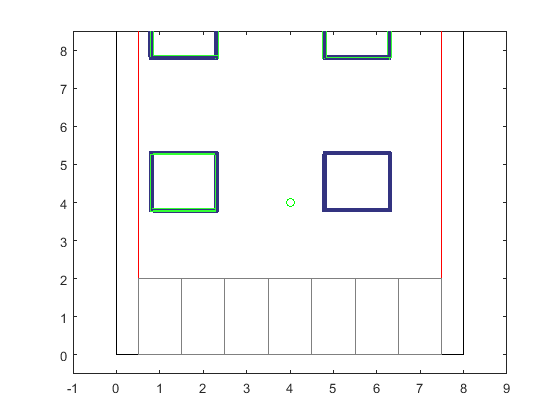

hold off

### TO DO:

- Wirklich alle Fälle abdecken (Türen unten Fenster)